clc; clear all; close all;

#### Establish Parameters

N_Training = 16;    % Sets of Training Data 
N_XData = 84;       % Sets of True Data 
Bits_per_set = 48;  % Bits per set of data
n_data = N_XData+N_Training;
Bits_per_block_Guard = 64; %Bits per block with guard data and pilot signals
size_training_data = Bits_per_set*N_Training;       % Size of Training Data - 16 sets of 64 bits: 1024
size_X = Bits_per_set*N_XData;                      % Size of data - 84 sets of 64 bits: 5376 bits

#### Generate Data

range = [-1 1]; % List of wanted values: 
a = randi(2,size_X,1); %Randomly select index
b = randi(2,size_training_data,1); 

X_k = transpose(range(a)); %Creates array with range(a) values
X_train = transpose(range(b)); % Creates Training Data
message = [X_train ; X_k]; %Combines data

Add guard data and pilot signals

Prep_data = zeros(n_data*Bits_per_block_Guard,1);
Sub_data = zeros(64,1);
pre_guard = zeros(6,1);
post_guard = zeros(5,1);
location_center=33;
for N = 1:1:n_data
    Data_N = message(1 + Bits_per_set*(N-1):N*Bits_per_set); %Extracts data set n_data - 48 bit
    Sub_data(7:12)=Data_N(1:6); %First set of Data
    Sub_data(13) = 1; %First Pilot Tone
    Sub_data(14:25) = Data_N(7:18);
    Sub_data(26) = 1; %Second Pilot Tone
    Sub_data(27:32) = Data_N(19:24);
    Sub_data(34:39) = Data_N(25:30);
    Sub_data(40) = 1; %Third Pilot Tone
    Sub_data(41:52) = Data_N(31:42);
    Sub_data(53) = 1; %Fourth Pilot Tone
    Sub_data(54:59) = Data_N(43:48);
    Sub_data;
    %Obtain Cyclic Prefix
    Prep_data(1+64*(N-1):64*(N)) = Sub_data; %Append data into the tx_data vector
end

Move Data to Time Domain and add cyclic prefixes

tx_data = zeros(n_data*(80),1); %Empty vector for data to be transmitted

for x_time = 1:1:n_data
    Data_x_n = Prep_data(1 + 64*(x_time-1):x_time*64); %Extracts data set n_data - 64 bits
    Data_X_n = ifft(fftshift(Data_x_n));  %Obtains the ifft of the data: Frequency to Time- 64 bits
    cyclic_prefix = Data_X_n(49:end); % Obtains the last 16 bits of the data
    Prefix_w_data = [cyclic_prefix ; Data_X_n];%Concatonate the cyclic prefix to the data set - 80 bits
    tx_data(1+80*(x_time-1):80*(x_time)) = Prefix_w_data;%Append data into the tx_data vector
end

Add Preamble for Schmidl-Cox Algorithm

pre = randi([0,1],1,64); % 64 columns 1 row
pre(pre == 0) = -1; %Changes all zeroes to -1
pre = ifft(fftshift(pre)); %Move to time domain (64 point ifft)
preamble = [pre,pre,pre]; %192 columns, 1 row

preamble = preamble';
tx_data = [preamble; tx_data];

Write to .txt file

Symbol_period = 20;

pulse = ones(Symbol_period, 1);

% spread out the values in "bits" by Symbol_period
% first create a vector to store the values
x = zeros(Symbol_period*length(tx_data),1);

% assign every Symbol_period-th sample to equal a value from bits
x(1:Symbol_period:end) = tx_data;

% now convolve the single generic pulse with the spread-out bits
x_tx = conv(pulse, x);

first create a vector to store the interleaved real and imaginary values

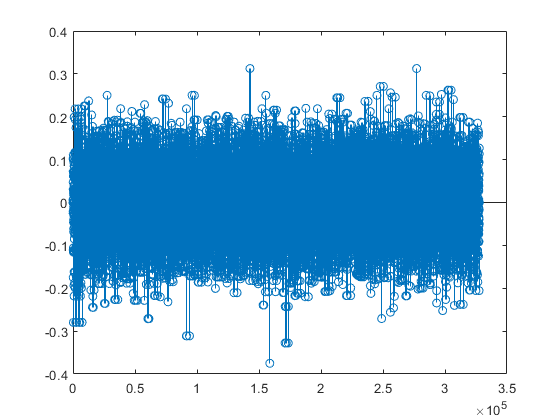

tmp = zeros(length(x_tx)*2, 1);

tmp(1:2:end) = real(x_tx);
tmp(2:2:end) = imag(x_tx);

figure
stem(tmp)

open a file to write in binary format 

f1 = fopen('tx1.dat', 'wb');
% write the values as a float32
fwrite(f1, tmp/2, 'float32');
% close the file
fclose(f1)

ans = 0